% 16-311 Homework 2 Framework
% Compiled by Hannah Lyness 1/9/19
% Form taken from:
% <https://www.mathworks.com/help/deeplearning/examples/create-simple-deep-learning-network-for-classification.html>

% Yiyun Wei
% yiyunwei

## Clear the workspace

close all
clc

## Load in the images

rootFolder = fullfile('images');
categories = {'hedgehogs', 'porcupines'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');

## Separate into training and testing (validation) data

table = countEachLabel(imds)

table = 2×2 table
      Label       Count
    __________    _____

    hedgehogs      15  
    porcupines     15  


smallestNumberOfImages =  min(table{:,2});

% This will randomly select 60% for training and save the others for validation
numTrainFiles = round(smallestNumberOfImages*0.6);
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## Define the neural network

layers = [
    % Start with an image input layer
    % Specify the dimensions of the images
    imageInputLayer([200 200 3])
    
    % Add a convluational layer.
    % To start with, choose a filter size of 20 by 20 and 100 total filters.
    % Add the options 'Padding', 'Same' so that we could
    % more easily change these numbers and add other layers.
    convolution2dLayer(10, 100, 'Padding', 'same')
    
    % Add a batch normalization layer
    batchNormalizationLayer
    
    % Add an activation function
    % We will use the rectified linear unit to test your training data, but
    % you can play around with different functions.
    softmaxLayer
    
    % Add a fully connected layer
    % The output size is the number of categories we want to sort the
    % images into
    fullyConnectedLayer(2)
    
    % Add a softmax activation layer
    softmaxLayer
    
    % Finally, classify the images using a classification layer
    classificationLayer
    
    ];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',16, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train and test the network

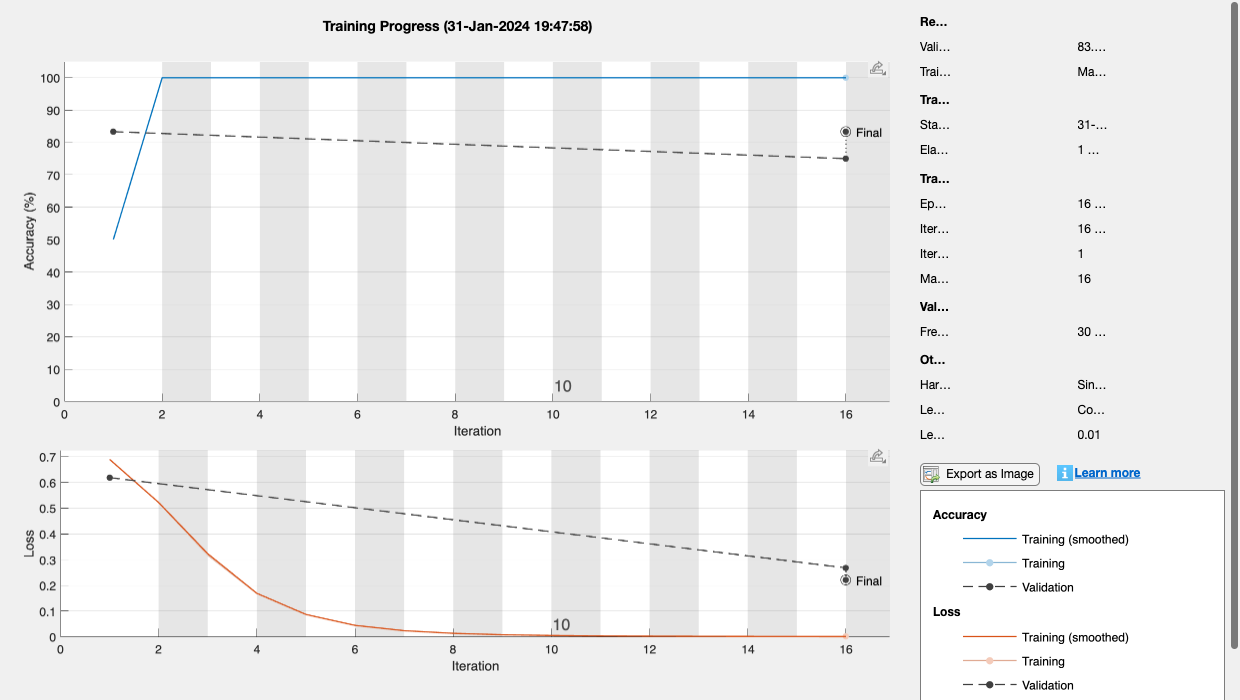

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

## Evaluate network

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.8333